close all
clear variables

fd = 100;
t = 0:1/fd:5;
fs = 1

fs = 1

f = sign(sin(2*fs*pi*t));

fg = figure

fg =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [520 378 560 420]
       Units: 'pixels'

  Show all properties


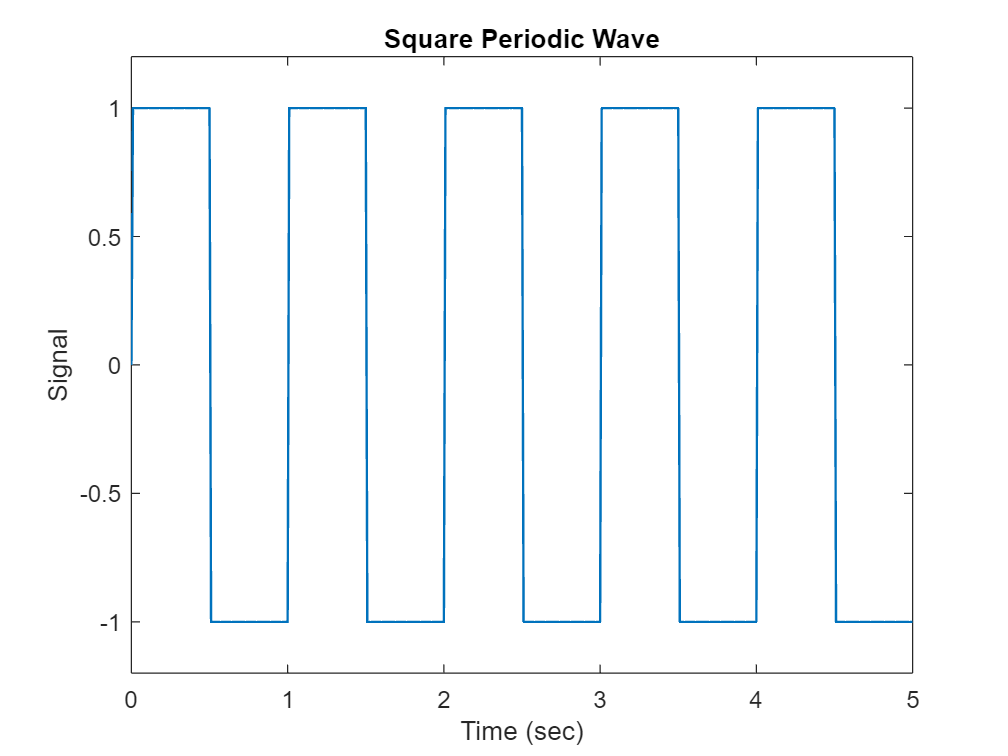

plot(t, f, 'LineWidth', 1)
axis([0 5 -1.2 1.2])
xlabel("Time (sec)")
ylabel("Signal")
title("Square Periodic Wave")
saveas(fg, 'lab_4-spectr\meandr.png')

N_sint = 10

N_sint = 10

f_sint = zeros(1, length(t))

f_sint =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



for i = 1 : length(t)
    total = 0;
    for j = 1 : N_sint
        total = total + sin(2*fs*pi*(2*j - 1) * t(i)) / (2*j - 1);
    end
    f_sint(i) = 4/pi * total;
end

fg1 = figure

fg1 =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [520 378 560 420]
       Units: 'pixels'

  Show all properties


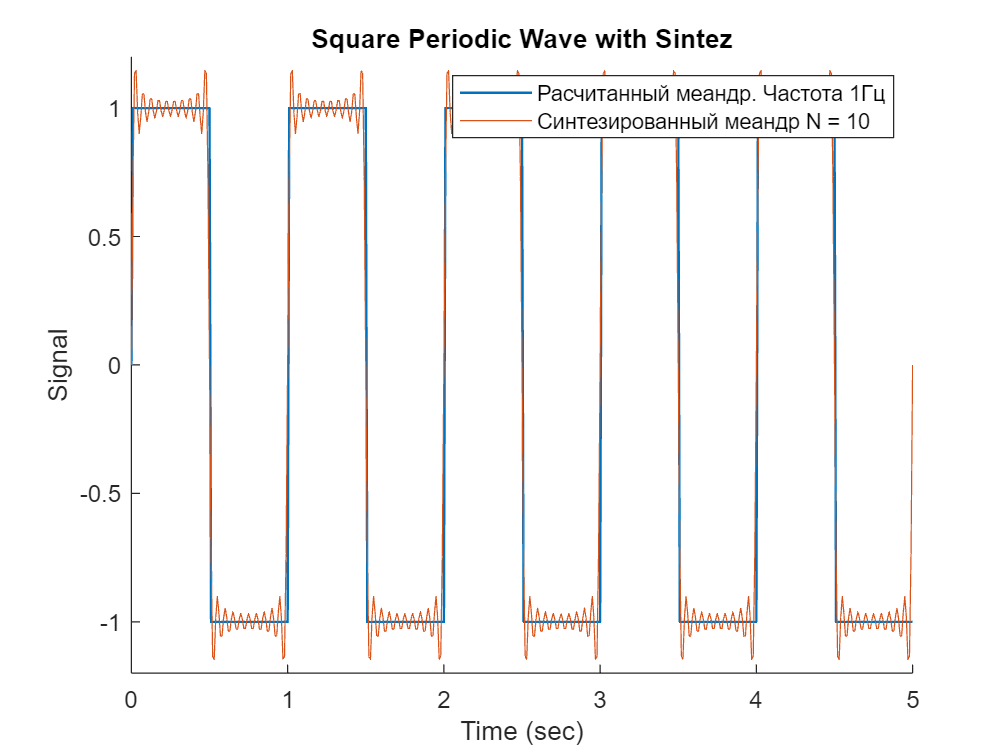

hold all
plot(t, f, 'LineWidth', 1)
plot(t, f_sint)
legend('Расчитанный меандр. Частота 1Гц', 'Синтезированный меандр N = 10')
hold off
axis([0 5 -1.2 1.2])
xlabel("Time (sec)")
ylabel("Signal")
title("Square Periodic Wave with Sintez")
saveas(fg1, 'lab_4-spectr\meandr_with_sintez.png')

N_harm = 8

N_harm = 8

f_harm = zeros(1, length(t))

f_harm =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



fg2 = figure

fg2 =   Figure (8) with properties:

      Number: 8
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [520 378 560 420]
       Units: 'pixels'

  Show all properties


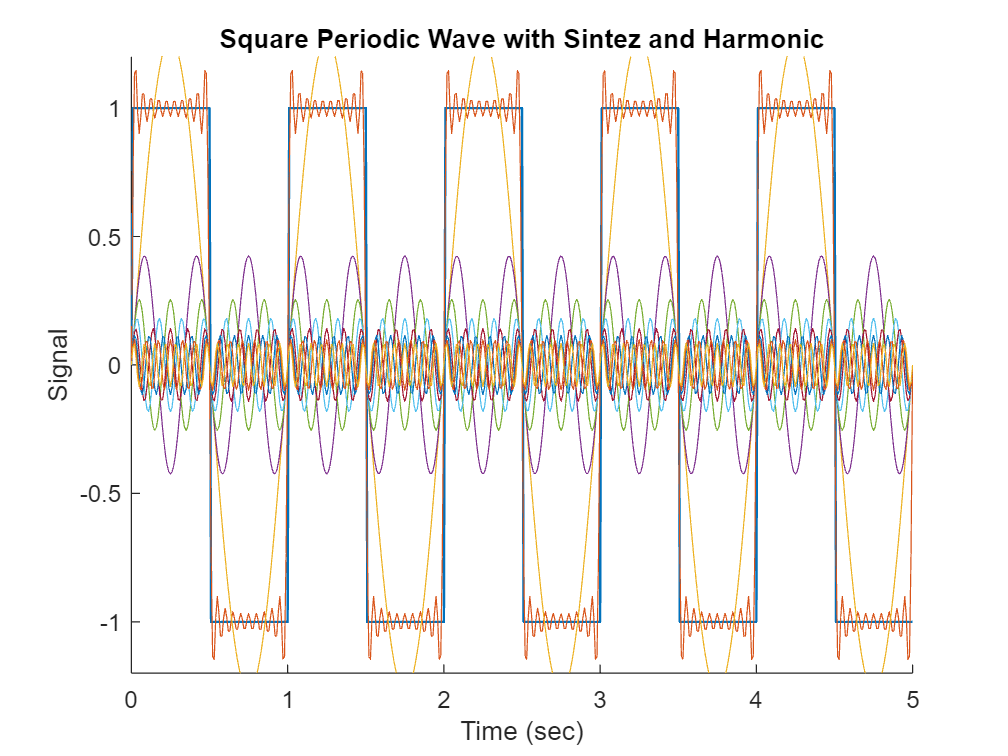

hold all
plot(t, f, 'LineWidth', 1)
plot(t, f_sint)
for j = 1 : N_harm
    for i = 1 : length(t)
        f_harm(i) = 4/pi * sin(2*fs*pi*(2*j - 1) * t(i)) / (2*j - 1);
    end
    plot(t, f_harm)
end
hold off
axis([0 5 -1.2 1.2])
xlabel("Time (sec)")
ylabel("Signal")
title("Square Periodic Wave with Sintez and Harmonic")
saveas(fg2, 'lab_4-spectr\meandr_with_sintez_harmonic.png')

fg3 = figure

fg3 =   Figure (9) with properties:

      Number: 9
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [520 378 560 420]
       Units: 'pixels'

  Show all properties



df0 = fd / length(f);
fk0 = 0 : df0 : fd/2 - df0

fk0 =          0    0.1996    0.3992    0.5988    0.7984    0.9980    1.1976    1.3972    1.5968    1.7964    1.9960    2.1956    2.3952    2.5948    2.7944    2.9940    3.1936    3.3932    3.5928    3.7924    3.9920    4.1916    4.3912    4.5908    4.7904    4.9900    5.1896    5.3892    5.5888    5.7884    5.9880    6.1876    6.3872    6.5868    6.7864    6.9860    7.1856    7.3852    7.5848    7.7844    7.9840    8.1836    8.3832    8.5828    8.7824    8.9820    9.1816    9.3812    9.5808    9.7804


X_meandr0 = fft(f)

X_meandr0 = 1.0e+02 *

   0.0000 + 0.0000i  -0.0000 - 0.0032i  -0.0000 - 0.0072i  -0.0000 - 0.0137i   0.0000 - 0.0305i   0.0000 - 3.1895i  -0.0000 + 0.0312i   0.0000 + 0.0139i   0.0000 + 0.0073i  -0.0000 + 0.0033i  -0.0000 + 0.0001i   0.0000 - 0.0032i   0.0000 - 0.0072i   0.0000 - 0.0135i  -0.0000 - 0.0299i   0.0000 - 1.0631i  -0.0000 + 0.0319i   0.0000 + 0.0141i   0.0000 + 0.0074i  -0.0000 + 0.0034i   0.0000 + 0.0001i  -0.0000 - 0.0031i   0.0000 - 0.0071i  -0.0000 - 0.0134i   0.0000 - 0.0293i  -0.0000 - 0.6378i  -0.0000 + 0.0326i   0.0000 + 0.0143i   0.0000 + 0.0075i  -0.0000 + 0.0035i  -0.0000 + 0.0002i  -0.0000 - 0.0030i  -0.0000 - 0.0070i  -0.0000 - 0.0132i  -0.0000 - 0.0287i   0.0000 - 0.4556i  -0.0000 + 0.0333i  -0.0000 + 0.0145i  -0.0000 + 0.0076i   0.0000 + 0.0035i   0.0000 + 0.0003i  -0.0000 - 0.0030i  -0.0000 - 0.0069i   0.0000 - 0.0130i   0.0000 - 0.0281i   0.0000 - 0.3543i  -0.0000 + 0.0341i   0.0000 + 0.0147i   0.0000 + 0.0077i  -0.0000 + 0.0036i


X0 = abs(X_meandr0(1, 1 : length(fk0))) / length(fk0)

X0 =          0    0.0013    0.0029    0.0055    0.0122    1.2758    0.0125    0.0056    0.0029    0.0013    0.0000    0.0013    0.0029    0.0054    0.0120    0.4252    0.0127    0.0056    0.0030    0.0014    0.0001    0.0012    0.0028    0.0053    0.0117    0.2551    0.0130    0.0057    0.0030    0.0014    0.0001    0.0012    0.0028    0.0053    0.0115    0.1822    0.0133    0.0058    0.0031    0.0014    0.0001    0.0012    0.0027    0.0052    0.0112    0.1417    0.0136    0.0059    0.0031    0.0014



df = fd / length(f_sint);
fk = 0 : df : fd/2 - df

fk =          0    0.1996    0.3992    0.5988    0.7984    0.9980    1.1976    1.3972    1.5968    1.7964    1.9960    2.1956    2.3952    2.5948    2.7944    2.9940    3.1936    3.3932    3.5928    3.7924    3.9920    4.1916    4.3912    4.5908    4.7904    4.9900    5.1896    5.3892    5.5888    5.7884    5.9880    6.1876    6.3872    6.5868    6.7864    6.9860    7.1856    7.3852    7.5848    7.7844    7.9840    8.1836    8.3832    8.5828    8.7824    8.9820    9.1816    9.3812    9.5808    9.7804


X_meandr = fft(f_sint)

X_meandr = 1.0e+02 *

   0.0000 + 0.0000i   0.0000 - 0.0032i   0.0001 - 0.0071i   0.0003 - 0.0135i   0.0008 - 0.0302i   0.1000 - 3.1870i  -0.0012 + 0.0316i  -0.0006 + 0.0144i  -0.0004 + 0.0079i  -0.0002 + 0.0040i  -0.0000 + 0.0008i   0.0002 - 0.0024i   0.0005 - 0.0063i   0.0010 - 0.0125i   0.0025 - 0.0287i   0.0996 - 1.0558i  -0.0033 + 0.0328i  -0.0016 + 0.0152i  -0.0010 + 0.0087i  -0.0006 + 0.0047i  -0.0002 + 0.0016i   0.0002 - 0.0016i   0.0007 - 0.0054i   0.0017 - 0.0115i   0.0041 - 0.0271i   0.0989 - 0.6256i  -0.0056 + 0.0339i  -0.0027 + 0.0159i  -0.0017 + 0.0094i  -0.0010 + 0.0055i  -0.0004 + 0.0024i   0.0001 - 0.0007i   0.0009 - 0.0045i   0.0022 - 0.0104i   0.0055 - 0.0254i   0.0978 - 0.4385i  -0.0080 + 0.0348i  -0.0039 + 0.0166i  -0.0025 + 0.0101i  -0.0016 + 0.0062i  -0.0008 + 0.0031i  -0.0000 + 0.0001i   0.0009 - 0.0035i   0.0026 - 0.0093i   0.0067 - 0.0235i   0.0964 - 0.3325i  -0.0106 + 0.0356i  -0.0052 + 0.0173i  -0.0033 + 0.0108i  -0.0022 + 0.0070i


X = abs(X_meandr(1, 1 : length(fk))) / length(fk)

X =     0.0000    0.0013    0.0028    0.0054    0.0121    1.2754    0.0126    0.0058    0.0032    0.0016    0.0003    0.0010    0.0025    0.0050    0.0115    0.4242    0.0132    0.0061    0.0035    0.0019    0.0006    0.0006    0.0022    0.0047    0.0110    0.2534    0.0137    0.0065    0.0038    0.0022    0.0010    0.0003    0.0018    0.0043    0.0104    0.1797    0.0143    0.0068    0.0042    0.0026    0.0013    0.0001    0.0015    0.0038    0.0098    0.1385    0.0148    0.0072    0.0045    0.0029


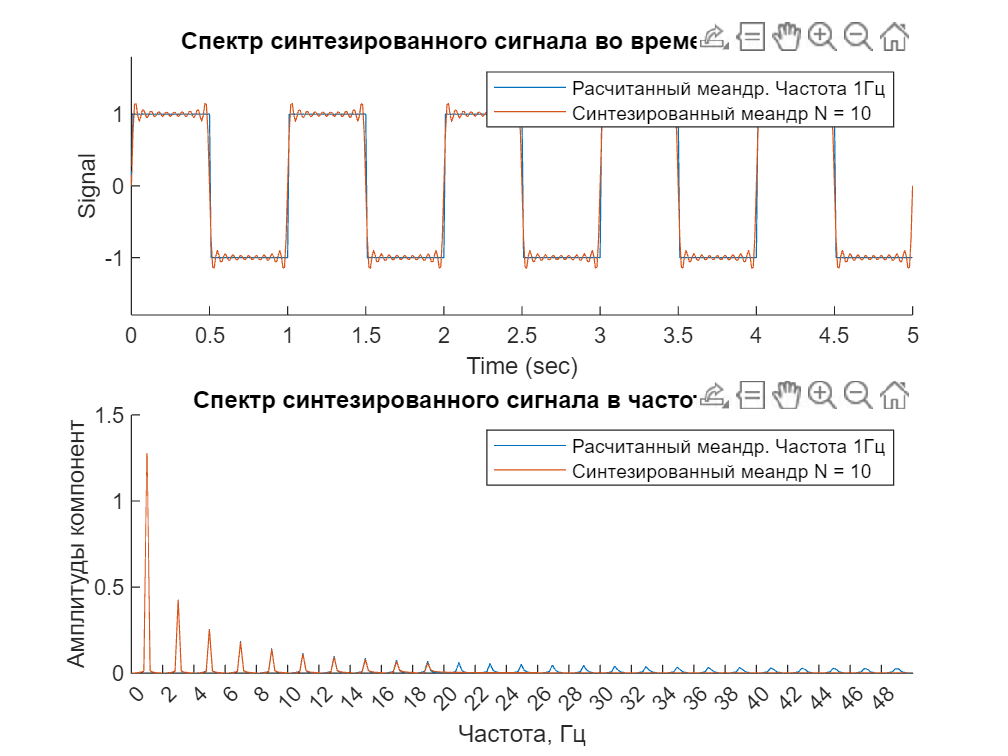


subplot(2, 1, 1)
hold all
plot(t, f)
plot(t, f_sint)
hold off
axis([0 5 -1.8 1.8])
title("Спектр синтезированного сигнала во временной области")
xlabel("Time (sec)")
ylabel("Signal")
legend('Расчитанный меандр. Частота 1Гц', 'Синтезированный меандр N = 10')

subplot(2, 1, 2)
hold all
plot(fk0, X0)
plot(fk, X)
hold off
xlabel('Частота, Гц');
ylabel('Амплитуды компонент');
title("Спектр синтезированного сигнала в частотной области")
xticks([0: 2 :(fd/2)-df])
legend('Расчитанный меандр. Частота 1Гц', 'Синтезированный меандр N = 10')

fg4 = figure

fg4 =   Figure (18) with properties:

      Number: 18
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [520 378 560 420]
       Units: 'pixels'

  Show all properties


X_a = awgn(f_sint, 10)

X_a =    -0.1988    0.8459    1.5476    1.2610    1.2270    1.2981    0.9240    1.3548    1.0165    1.6502    1.0288    0.8094    1.0677    0.8045    0.5069    1.0715    1.0609    1.2355    0.7616    0.7355    0.8114    0.6714    1.8770    1.1435    0.7837    1.1024    1.3791    1.2403    1.3158    1.1415    0.4900    0.7498    1.3640    0.9661    1.0693    1.1363    0.6659    1.0964    0.8984    0.5158    1.0708    0.7192    0.8969    0.6313    0.7739    1.0401    1.4798    0.7876    1.2441    0.8987



df_1 = fd / length(X_a);
fk_1 = 0 : df_1 : fd/2 - df_1

fk_1 =          0    0.1996    0.3992    0.5988    0.7984    0.9980    1.1976    1.3972    1.5968    1.7964    1.9960    2.1956    2.3952    2.5948    2.7944    2.9940    3.1936    3.3932    3.5928    3.7924    3.9920    4.1916    4.3912    4.5908    4.7904    4.9900    5.1896    5.3892    5.5888    5.7884    5.9880    6.1876    6.3872    6.5868    6.7864    6.9860    7.1856    7.3852    7.5848    7.7844    7.9840    8.1836    8.3832    8.5828    8.7824    8.9820    9.1816    9.3812    9.5808    9.7804


X_a_meander = fft(X_a)

X_a_meander = 1.0e+02 *

  -0.0534 + 0.0000i   0.0575 - 0.0358i   0.0436 - 0.0180i  -0.0609 + 0.0147i   0.0328 - 0.0826i   0.1496 - 3.2120i   0.0311 - 0.0084i   0.0372 + 0.1120i   0.0153 - 0.0031i   0.0284 + 0.0889i  -0.0521 - 0.0315i  -0.0317 - 0.0476i   0.0308 - 0.0479i  -0.0362 - 0.0607i  -0.0334 + 0.0011i   0.0786 - 1.0450i   0.0070 + 0.0406i   0.0358 + 0.0219i   0.0155 - 0.0374i   0.1365 - 0.0042i   0.0460 - 0.0569i  -0.0675 - 0.1145i   0.0163 + 0.0364i   0.0291 - 0.0683i   0.1084 - 0.1126i   0.0425 - 0.6254i  -0.0095 - 0.0118i  -0.0098 + 0.0551i  -0.0607 + 0.0620i   0.0944 - 0.0235i   0.0025 + 0.0827i   0.0499 - 0.0370i  -0.1094 - 0.0378i  -0.0583 + 0.0352i  -0.0706 + 0.0080i   0.1349 - 0.3980i  -0.0349 + 0.0851i  -0.0701 - 0.0208i   0.0011 - 0.0160i  -0.0357 + 0.1331i  -0.0496 - 0.0516i  -0.0011 - 0.0387i  -0.1494 + 0.0445i   0.0506 - 0.0854i   0.0977 + 0.0332i   0.0080 - 0.3607i   0.0044 + 0.0060i  -0.0267 - 0.0117i  -0.0517 - 0.0063i  -0.0657 - 0.0444i


X_f = abs(X_a_meander(1, 1 : length(fk_1))) / length(fk_1)

X_f =     0.0214    0.0271    0.0189    0.0250    0.0355    1.2862    0.0129    0.0472    0.0063    0.0373    0.0243    0.0229    0.0228    0.0283    0.0134    0.4192    0.0165    0.0168    0.0162    0.0546    0.0293    0.0532    0.0159    0.0297    0.0625    0.2507    0.0061    0.0224    0.0347    0.0389    0.0331    0.0249    0.0463    0.0272    0.0284    0.1681    0.0368    0.0292    0.0064    0.0551    0.0286    0.0155    0.0624    0.0397    0.0413    0.1443    0.0030    0.0117    0.0208    0.0317


fg5 = figure

fg5 =   Figure (19) with properties:

      Number: 19
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [520 378 560 420]
       Units: 'pixels'

  Show all properties



X_a_sr = meanfilt(transpose(X_a), 5)

X_a_sr =     0.3594    0.6514    0.9365    1.2359    1.2515    1.2130    1.1641    1.2487    1.1948    1.1719    1.1145    1.0721    0.8435    0.8520    0.9023    0.9359    0.9273    0.9730    0.9210    0.8431    0.9714    1.0478    1.0574    1.1156    1.2572    1.1298    1.1643    1.2358    1.1133    0.9875    1.0122    0.9423    0.9278    1.0571    1.0403    0.9868    0.9733    0.8626    0.8495    0.8601    0.8202    0.7668    0.8184    0.8123    0.9644    0.9425    1.0651    1.0901    0.9481    0.5852



df_2 = fd / length(X_a);
fk_2 = 0 : df_2 : fd/2 - df_2

fk_2 =          0    0.1996    0.3992    0.5988    0.7984    0.9980    1.1976    1.3972    1.5968    1.7964    1.9960    2.1956    2.3952    2.5948    2.7944    2.9940    3.1936    3.3932    3.5928    3.7924    3.9920    4.1916    4.3912    4.5908    4.7904    4.9900    5.1896    5.3892    5.5888    5.7884    5.9880    6.1876    6.3872    6.5868    6.7864    6.9860    7.1856    7.3852    7.5848    7.7844    7.9840    8.1836    8.3832    8.5828    8.7824    8.9820    9.1816    9.3812    9.5808    9.7804


X_a_meander_sr = fft(X_a_sr)

X_a_meander_sr = 1.0e+02 *

  -0.0532 + 0.0000i   0.0578 - 0.0358i   0.0438 - 0.0180i  -0.0605 + 0.0146i   0.0330 - 0.0824i   0.1492 - 3.1995i   0.0312 - 0.0084i   0.0372 + 0.1110i   0.0155 - 0.0032i   0.0283 + 0.0876i  -0.0510 - 0.0311i  -0.0309 - 0.0468i   0.0303 - 0.0470i  -0.0350 - 0.0593i  -0.0321 + 0.0009i   0.0762 - 1.0086i   0.0070 + 0.0388i   0.0344 + 0.0207i   0.0150 - 0.0357i   0.1291 - 0.0042i   0.0434 - 0.0537i  -0.0626 - 0.1070i   0.0154 + 0.0334i   0.0270 - 0.0631i   0.0991 - 0.1030i   0.0387 - 0.5659i  -0.0082 - 0.0109i  -0.0084 + 0.0486i  -0.0532 + 0.0543i   0.0827 - 0.0209i   0.0025 + 0.0711i   0.0430 - 0.0321i  -0.0923 - 0.0324i  -0.0484 + 0.0290i  -0.0580 + 0.0062i   0.1107 - 0.3259i  -0.0278 + 0.0683i  -0.0555 - 0.0170i   0.0012 - 0.0131i  -0.0273 + 0.1029i  -0.0376 - 0.0400i  -0.0005 - 0.0297i  -0.1107 + 0.0326i   0.0375 - 0.0631i   0.0708 + 0.0234i   0.0061 - 0.2564i   0.0035 + 0.0036i  -0.0178 - 0.0086i  -0.0343 - 0.0049i  -0.0430 - 0.0300i


X_f_sr = abs(X_a_meander_sr(1, 1 : length(fk_2))) / length(fk_2)

X_f_sr =     0.0213    0.0272    0.0190    0.0249    0.0355    1.2812    0.0129    0.0468    0.0063    0.0368    0.0239    0.0224    0.0224    0.0275    0.0128    0.4046    0.0158    0.0161    0.0155    0.0517    0.0276    0.0496    0.0147    0.0274    0.0572    0.2269    0.0055    0.0197    0.0304    0.0341    0.0285    0.0215    0.0391    0.0226    0.0233    0.1377    0.0295    0.0232    0.0053    0.0426    0.0220    0.0119    0.0462    0.0293    0.0298    0.1026    0.0020    0.0079    0.0139    0.0210


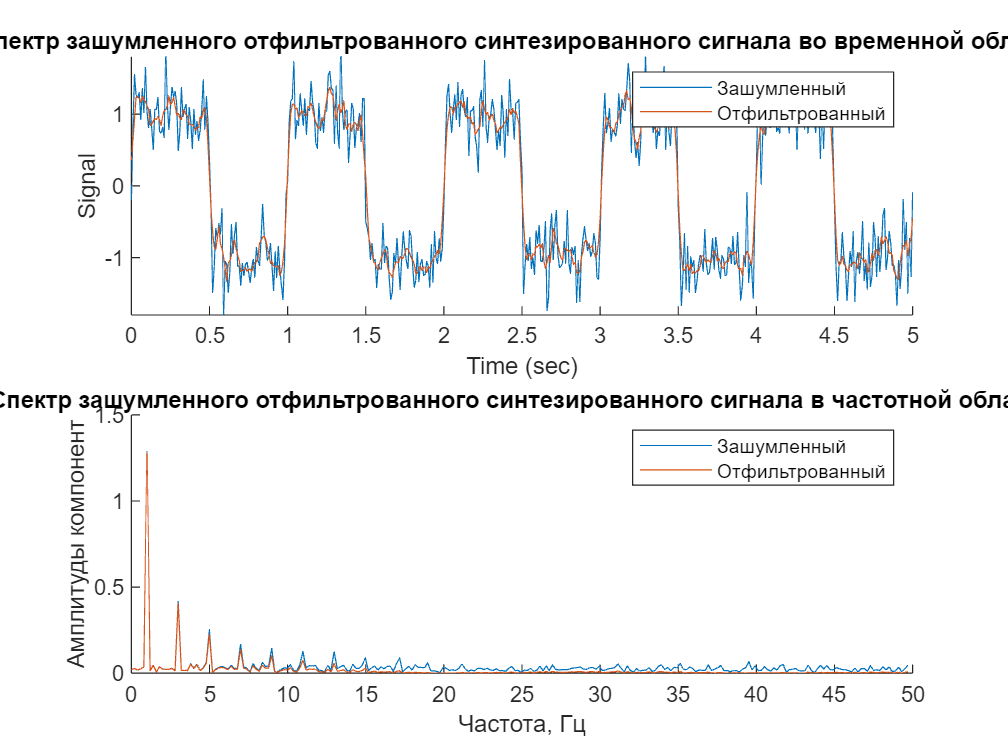


subplot(2, 1, 1)
hold all
plot(t, X_a)
plot(t, X_a_sr)
hold off
axis([0 5 -1.8 1.8])
title("Спектр зашумленного отфильтрованного синтезированного сигнала во временной области")
xlabel("Time (sec)")
ylabel("Signal")
legend('Зашумленный', 'Отфильтрованный')

subplot(2, 1, 2)
hold all
plot(fk_1, X_f)
plot(fk_1, X_f_sr)
hold off
title("Спектр зашумленного отфильтрованного синтезированного сигнала в частотной области")
xlabel('Частота, Гц');
ylabel('Амплитуды компонент');
legend('Зашумленный', 'Отфильтрованный')

function y = meanfilt(x, N)
    y = zeros(1, length(x));
    x = apdate(x, N);
    for i = 1 : (length(x) - (N - 1))
        y(i) = sum(x(i:i+(N-1)))/N;
    end
end

function x_new = apdate(x, N)
    if mod(N-1, 2) == 0
        for i = 1 : (N-1)/2
            x = [x(1, 1); x];
        end
        for i = 1 : (N-1)/2
            x = [x; x(length(x), 1)];
        end
    else
        for i = 1 : (N)/2
            x = [x(1, 1); x];
        end
        for i = 1 : (N-2)/2
            x = [x; x(length(x), 1)];
        end
    end
    x_new = x;
end